# Overview of productivity catalog:

load analysis_catalog.mat

## Basic variables

All variables are presented in SI units if not otherwise indicated

M                   = CAT.MSmag;
Mo                  = 10.^((M+10.7)*3/2)/10^7;
depth               = CAT.MSdepth*1000;
productivity        = CAT.MSprod;
residualProductivity= CAT.MSres;
MeBB                = CAT.MeBB_appended_cat1;
MeHF                = CAT.MeHF_appended_cat1;
meanSlip            = CAT.av_slip_appended_cat2;
faultWidth          = CAT.rwid_appended_cat2*1000;
faultLength         = CAT.rlen_appended_cat2*1000;
faultPerimeter      = CAT.Perimeter_appended_cat2;
stressDrop          = CAT.StressDrop_appended_cat2*10^6;
heterogeneity       = CAT.EllipseErrorNorm_appended_cat2;

## Productivity law:

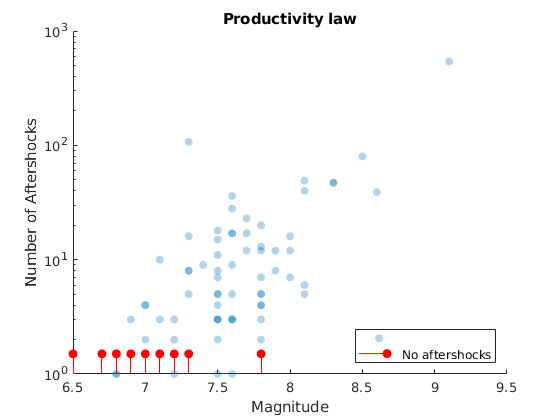

figure
scatter(M,productivity,'filled', 'MarkerFaceAlpha',0.3)
set(gca, 'YScale', 'log')
xlabel('Magnitude')
ylabel('Number of Aftershocks')
title('Productivity law')
hold on
stem(M(isinf(residualProductivity))',1.5*ones(1,sum(isinf(residualProductivity))),'r','filled')

legend({'','No aftershocks'},'Location','southeast')

## Stress Drop Calibration

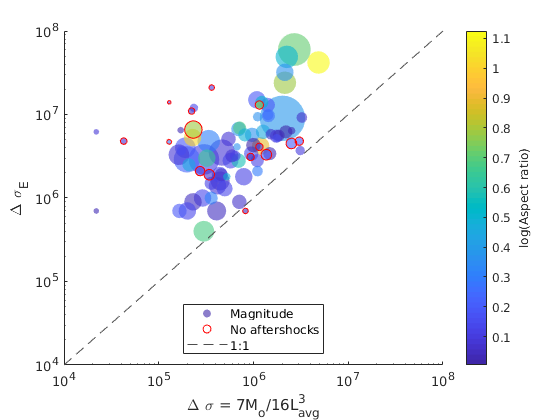

figure 
aspect = faultLength./faultWidth;
aspect(aspect<1) = (aspect(aspect<1)).^-1;

stressDropCalc = Mo*7/16./(sqrt(faultLength.*faultWidth)).^3;
scatter(stressDropCalc, stressDrop, (M-5).^5,log10(aspect), 'filled','MarkerFaceAlpha',0.6)
xlabel('\Delta \sigma = 7M_o/16L_{avg}^3')
ylabel('\Delta \sigma_E')
set(gca,'XScale','log', 'YScale','log')
set(gca,'YLim',[10^4,10^8])
set(gca,'XLim',[10^4,10^8])
hold on
Izip = isinf(residualProductivity);
scatter(stressDropCalc(Izip) , stressDrop(Izip), (M(Izip)-5).^5, 'r')
plot([10^4,10^8],[10^4,10^8],'--','Color',[0.3, 0.3, 0.3])
legend({'Magnitude','No aftershocks', '1:1'},'Location','south')
c = colorbar;
c.Label.String = 'log(Aspect ratio)';

## Residuals versus Stress Drop

An important result that arises here. Stress drop calculation on the left are made from order of magnitude estimations that assume cicuar rupture. For this original calculation there does appear to be a weak correlation between stress drop and productivity. However, this result is put in question by more robust estimations of stress drop from finite fault source inversions. With these new figures, there appears to be no correlation. Interestingly, the general topology of the original relationship closely resembles that of productivity versus aspect. The correspondence would imply that the apparent relationship between stress drop and productivity may instead just be an artefact of source geometry percolating through the stress drop calculation. Perhaps these results suggest that source geometry, particularly the shape,  plays a more determining role in the production of aftershocks. Specifically, long and skinny ruptures are constrained in their maximum pructivity by the limits of the Scizosphere. 

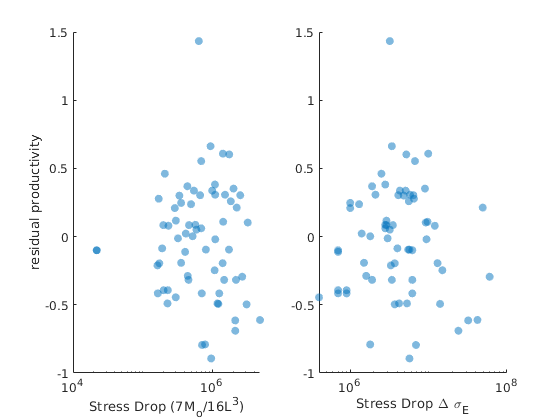

figure
subplot(1,2,1)
scatter(Mo*7/16./(sqrt(faultLength.*faultWidth)).^3,residualProductivity, 'filled','MarkerFaceAlpha',0.5)
xlabel('Stress Drop (7M_o/16L^3)')
set(gca,'XScale','log')

subplot(1,2,2)
scatter(stressDrop,residualProductivity,'filled','MarkerFaceAlpha',0.5)
xlabel('Stress Drop \Delta \sigma_E')
ylabel('residual productivity')
set(gca,'XScale','log')
title('Stress Drop sensitivty')

subplot(1,2,1)
ylabel('residual productivity')
subplot(1,2,2)
ylabel('')

subplot(1,2,2)
title('')

## Residuals versus aspect ratio

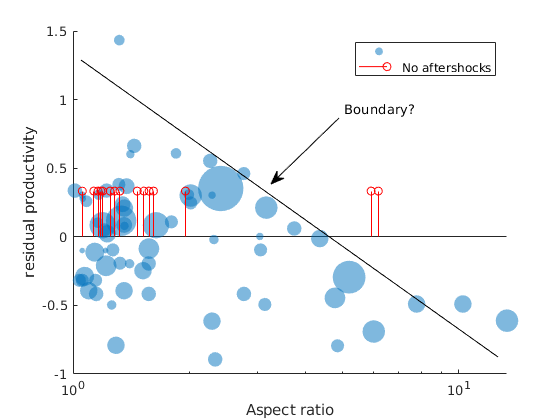

figure
aspect = faultLength./faultWidth;
aspect(aspect<1) = (aspect(aspect<1)).^-1;
scatter(aspect,residualProductivity,(M-5).^5,'filled','MarkerFaceAlpha',0.5)
xlabel('Aspect ratio')
ylabel('residual productivity')
set(gca,'XScale','log')
hold on 
stem(aspect(isinf(residualProductivity))', ones(1,sum(isinf(residualProductivity)))/3,'r')

annotation('line',[0.1446 0.8893],[0.8571 0.15])
annotation('textarrow',[0.6054 0.4839],[0.719 0.5619],'String','Boundary?')

legend({'','No aftershocks'})

## Aspect versus Magnitude

To ensure that the cluster of earthquakes with no aftershocks but relatively equant shape (aspect ratio ~ 1) is not an artifact of the poor resolution on smaller earthquakes, I also test the sensitivity of the aspect ratio to magnitude.

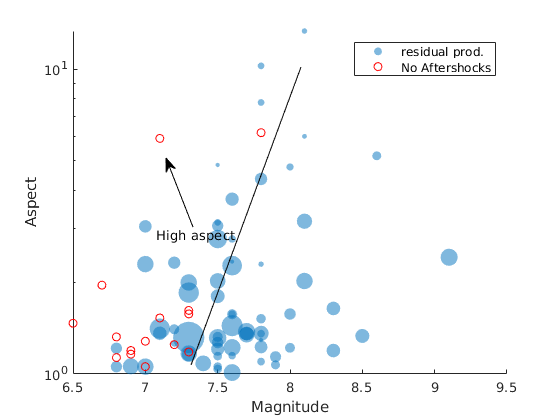

figure 
scatter(M(~isinf(residualProductivity)),aspect(~isinf(residualProductivity)), (10*(residualProductivity(~isinf(residualProductivity)) - min(residualProductivity(~isinf(residualProductivity))))).^2 + 10,'filled','MarkerFaceAlpha',0.5)
xlabel('Magnitude')
ylabel('Aspect')
set(gca,'YScale','log')
hold on 
scatter(M(isinf(residualProductivity)),aspect(isinf(residualProductivity)),'r')

annotation('line',[0.5375 0.3411],[0.8405 0.131])
annotation('textarrow',[0.3446 0.2964],[0.4595 0.6238],'String','High aspect')

legend({'residual prod.','No Aftershocks'})

The preceeding figures seems to imply that aspect *limits* the productivity of earthquakes. Within its limits there still existist substantial variation in aftershock productivity.

## Residual versus heterogeneity

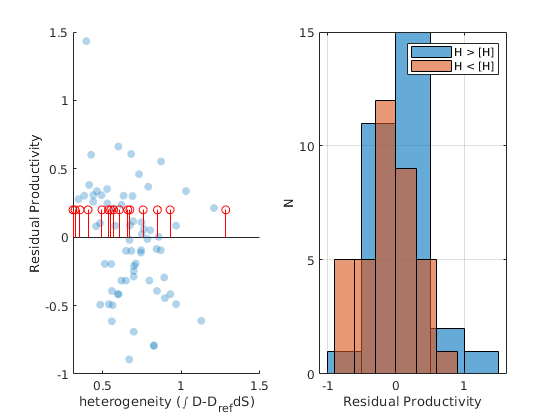

figure
subplot(1,2,1)
scatter(heterogeneity,residualProductivity,'filled', 'MarkerFaceAlpha',0.3)
xlabel('heterogeneity (\int D-D_{ref}dS)')
ylabel('Residual Productivity')
hold on
stem(heterogeneity(isinf(residualProductivity))', ones(1,sum(isinf(residualProductivity)))/5,'r')

subplot(1,2,2)
histogram(residualProductivity(heterogeneity<mean(heterogeneity)))
hold on
histogram(residualProductivity(heterogeneity>mean(heterogeneity)))


grid on

subplot(1,2,2)
legend({'H > [H]','H < [H]'})
xlabel('Residual Productivity')
ylabel('N')

## Residual versus Radiated energy

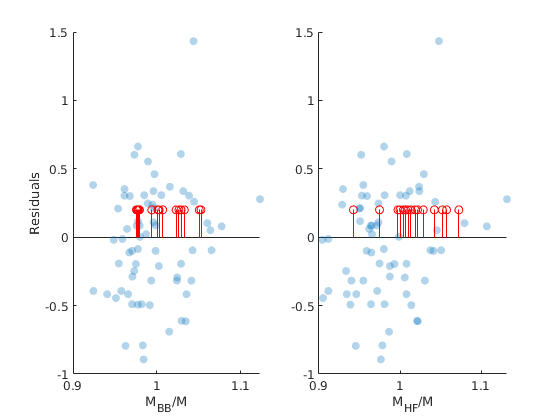

figure
subplot(1,2,1)
scatter(MeBB./M,residualProductivity,'filled', 'MarkerFaceAlpha',0.3)
hold on 
stem(MeBB(isinf(residualProductivity))'./M(isinf(residualProductivity))', ones(1,sum(isinf(residualProductivity)))/5,'r')
subplot(1,2,2)
scatter(MeHF./M,residualProductivity,'filled', 'MarkerFaceAlpha',0.3)
hold on
stem(MeHF(isinf(residualProductivity))'./M(isinf(residualProductivity))', ones(1,sum(isinf(residualProductivity)))/5,'r')

subplot(1,2,1)
xlabel('M_{BB}/M')
ylabel('Residuals')
subplot(1,2,2)
xlabel('M_{HF}/M')

## Model comparison: Area vs. Taurus

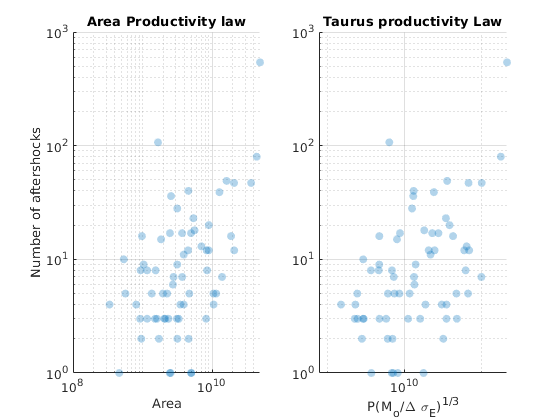

figure
subplot(1,2,1)
scatter(faultLength.*faultWidth,productivity, 'filled', 'MarkerFaceAlpha',0.3)
xlabel('Area')
set(gca,'XScale', 'log','YScale', 'log')

subplot(1,2,2)
scatter((Mo./stressDrop).^(1/3).*faultPerimeter, productivity,  'filled', 'MarkerFaceAlpha',0.3)
xlabel('P({M_o/\Delta \sigma_E})^{1/3}')
set(gca,'XScale', 'log','YScale', 'log')

subplot(1,2,1)
grid on
title('Area Productivity law')
subplot(1,2,2)
grid on
title('Taurus productivity Law')

subplot(1,2,1)
ylabel('Number of aftershocks')

## Residual vs. Perimeter tortuosity

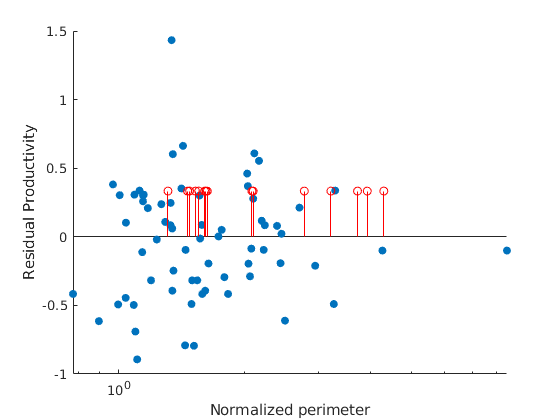

figure
normPerimeter = faultPerimeter./(2*pi*(Mo*7/16./stressDrop).^(1/3));
scatter(normPerimeter, residualProductivity, 'filled')
xlabel('Normalized perimeter')
ylabel('Residual Productivity')
hold on 
stem(normPerimeter(isinf(residualProductivity))', ones(1,sum(isinf(residualProductivity)))/3,'r')
set(gca,'XScale', 'log')

## Depth normalization

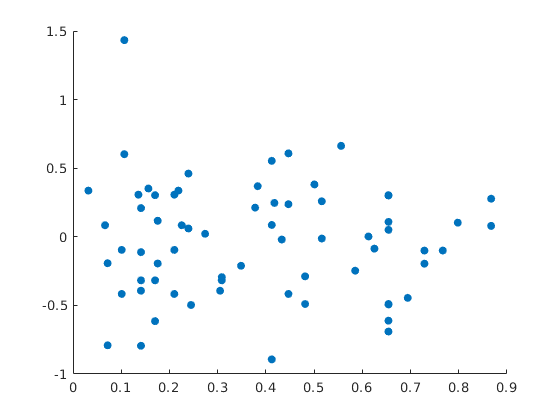

figure 
depthNorm = abs(depth-mean(depth))/mean(depth);
scatter(depthNorm,residualProductivity,'filled')

## Inversion